2(a)

clear;
clc;
load('SensorMeasurements.mat')

N = 2000;
len = 1:1:N;

% find the mean of calibration from v10 and v20, then get
% the exact C from both
data = [CalibrationSequenceVelocity_v0; CalibrationSequenceVelocity_v10; CalibrationSequenceVelocity_v20];
mean_vel_0 = mean(data(1,:)); 
mean_vel_10 = mean(data(2,:)); 
mean_vel_20 = mean(data(3,:));
C = (mean_vel_0+mean_vel_10+mean_vel_20)/3/10;

for i = 1:3
    mean_vel(i) = mean(data(i,:));
    cov_rvk(i) = var(data(i,:))/C^2; %vary=c^2*P_r
end

cov_rvk_mean = mean(cov_rvk);
% Display the results
disp(['Scaling constant C: ' num2str(C)]);

Scaling constant C: 1.0999


disp(['Variance of the velocity sensor noise Var[r_vk]: ' num2str(cov_rvk_mean)]);

Variance of the velocity sensor noise Var[r_vk]: 2.4972


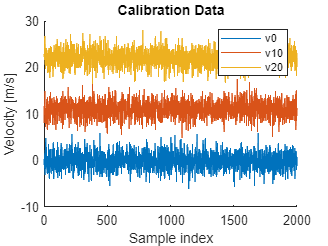


% Plot calibration data
figure(1); clf; hold on;
plot(len, CalibrationSequenceVelocity_v0)
plot(len, CalibrationSequenceVelocity_v10)
plot(len, CalibrationSequenceVelocity_v20)
title('Calibration Data')
xlabel('Sample index')
ylabel('Velocity [m/s]')
legend('v0', 'v10', 'v20')
hold off

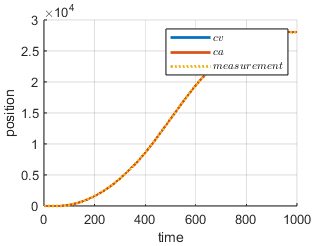


% Preprocess the data
y_seq = Generate_y_seq();
new_seq = y_seq(:, 1:2:end);
N = N/2;

% Define parameters for filtering of CV model
Tv = 0.2; % For 0.1sec, it has half Nan
A = [1, Tv; 0, 1];
H = [1, 0; 0, C];
cov = [1, 0; 0, C^2 * cov_rvk_mean];
Q = [0, 0; 0, 4];
x_0 = [0; 0]; % initial stationary
P_0 = [10, 0; 0, 10];

% Call kalmanFilter_vsk function to get v vector to get autocorrelation
[X_est, P, vk_v] = kalmanFilter_vsk(new_seq, x_0, P_0, A, Q, H, cov);

% Define CA model
A_ca = [1, Tv, Tv^2/2; 0, 1, Tv; 0, 0, 1];
H_ca = [1, 0, 0; 0, C, 0];
cov_ca = [1 0; 0 C^2*cov_rvk_mean];
Q_ca = [0, 0, 0; 0, 0, 0; 0, 0, 4];
x_0a = [0; 0; 0];
P_0a = 10*eye(3);
[X_esta, Pa, vk_a] = kalmanFilter_vsk(new_seq, x_0a, P_0a, A_ca, Q_ca, H_ca, cov_ca);

figure
hold on
plot(1:length(X_est), X_est(1,:), 'LineWidth', 2);
plot(1:length(X_est), X_esta(1,:), 'LineWidth', 2);
plot(1:length(X_est), new_seq(1,:), ':', 'LineWidth', 2);
legend('$cv$', '$ca$', '$measurement$', 'Interpreter','latex');
grid on
xlabel('time');
ylabel('position');
hold off

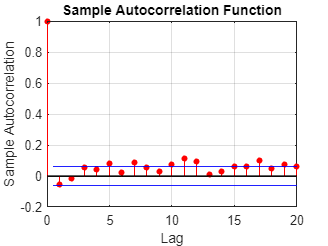

figure
autocorr(vk_v(1,:))

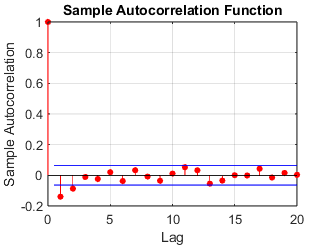

autocorr(vk_a(1,:))
hold off

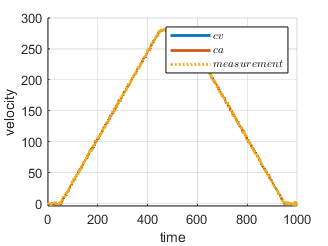

figure
hold on
plot(1:length(X_est), X_est(2,:), 'LineWidth', 2);
plot(1:length(X_est), X_esta(2,:), 'LineWidth', 2);
plot(1:length(X_est), new_seq(2,:)/C, ':', 'LineWidth', 2);
legend('$cv$', '$ca$', '$measurement$', 'Interpreter', 'latex');
grid on
xlabel('time');
ylabel('velocity');
hold off

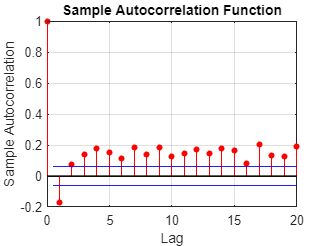

figure
autocorr(vk_v(2,:))

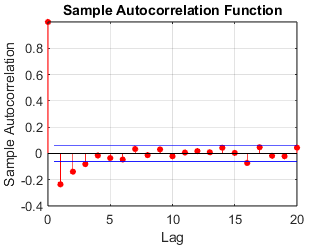

autocorr(vk_a(2,:))
hold off